# Фундаментальная частота прямоугольного сигнала

Создадим прямоугольный сигнал, и выберем частоту дискретизации такой величины, чтобы при прослушивании мы услышали Ля первой октавы - 440 Гц.

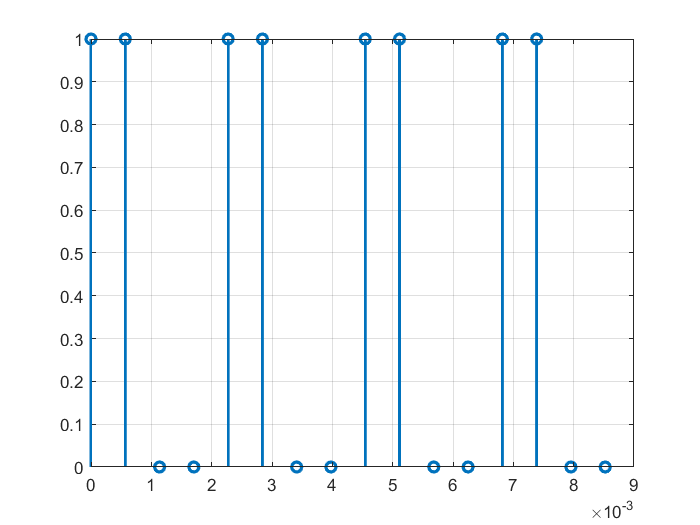

f0=440;
fs=4*f0;
dt=1/fs;
t=0:dt:1;
n=length(t);
one_period = [1 1 0 0];
sqwave = repmat(one_period, 1, 2000);
stem(t, sqwave(1:n), 'LineWidth',2);
xlim([0 0.009]);
grid on;

sound(sqwave(1:n), fs);

Сравним с синусойдой, которую мы генерировали в предыдущих видео:

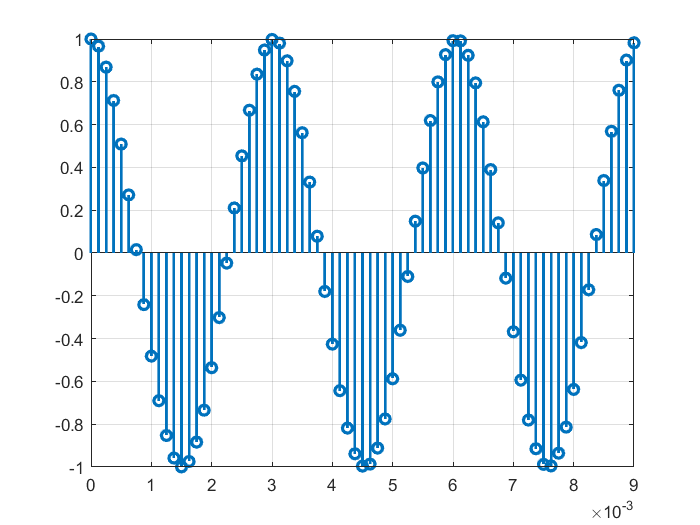

f0=330;
fs=8000;
dt=1/fs;
t=0:dt:1;
x=cos(2*pi*f0*t);
stem(t, x, 'LineWidth', 2);
xlim([0 0.009]);
grid on;

sound(x, fs);